# Sessió 10

**Yaiza Cano, Narcís Terrado **

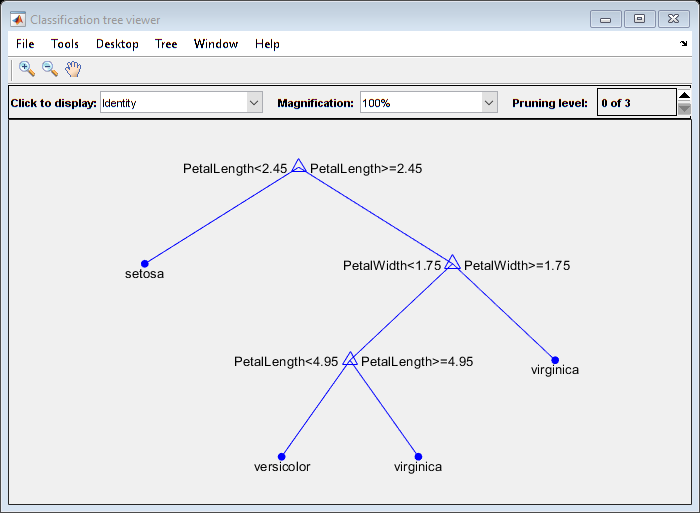

fishertable = readtable('fisheriris.csv');
view(trainedModel.ClassificationTree,'Mode','graph');

yfit = trainedModel.predictFcn(fishertable);

[trainedModel, validationAccuracy] = trainClassifier(fishertable);

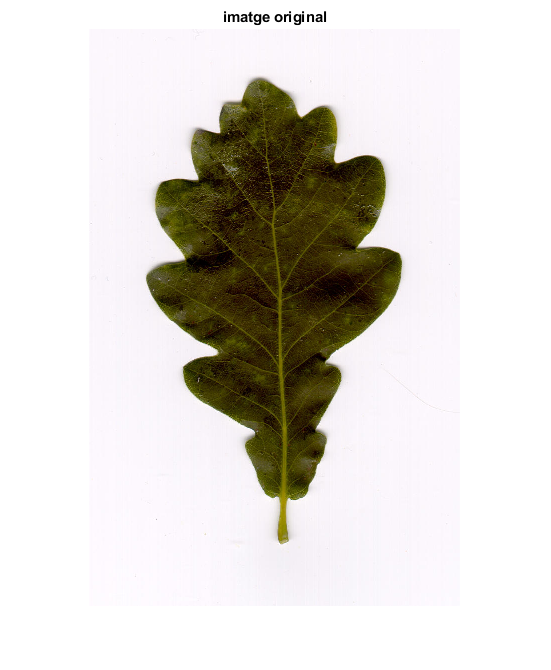

roure = imread("fulles\Roure\l4nr001.jpg");
figure, imshow(roure); title("imatge original")

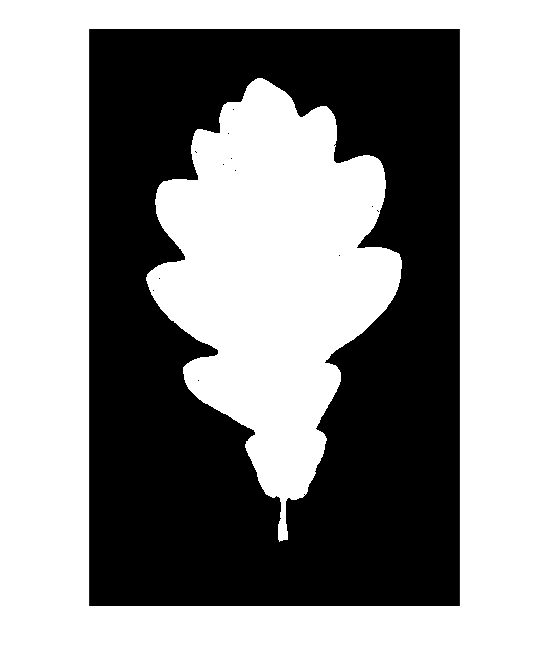

roure = rgb2gray(roure);
br = imbinarize(roure);
br = imcomplement(br);
figure, imshow(br);

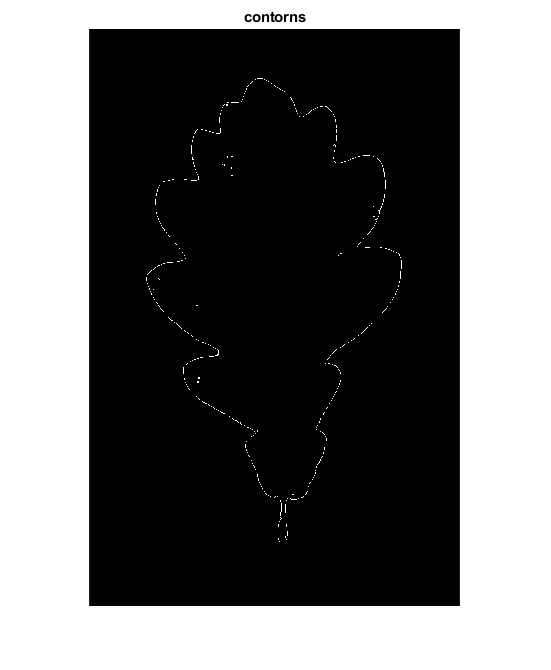



%obtenim el contorn
ero = imerode(br, strel('disk',1));
cont = xor(ero,br);
figure, imshow(cont), title("contorns");

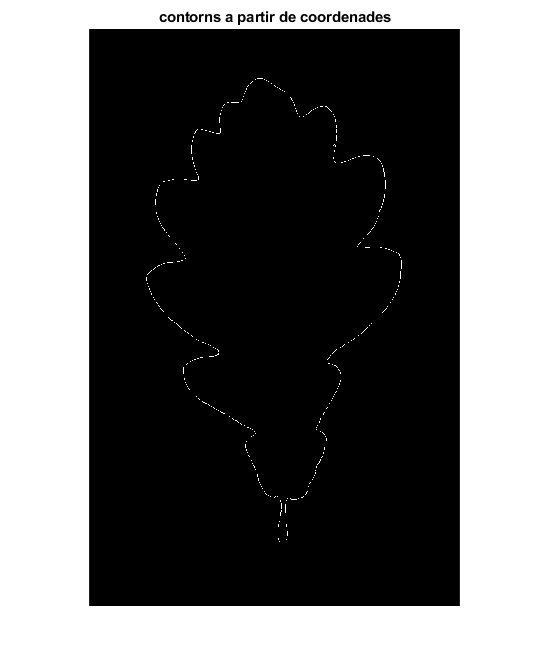


%obtenim les coordenades del contorn
[fila, col] = find(br, 1); %busquem el primer píxel
B = bwtraceboundary(br, [fila, col], 'E'); %direcció est a l'atzar
%B conté les coordenades

%Ho comprovem mostrant el resultat
aux = zeros(size(br));
aux(sub2ind(size(aux),B(:,1),B(:,2))) = 1;
figure, imshow(aux), title("contorns a partir de coordenades")

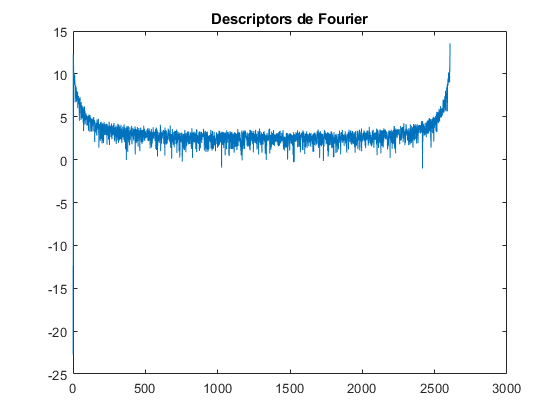


%centrem coordenades
mig = mean(B);
B(:,1) = B(:,1) - mig(1);
B(:,2) = B(:,2) - mig(2);

%convertim les coordenades a complexes
s = B(:,1) + 1i*B(:,2);

%cal que la dimensió del vector sigui parell
[mida, bobo]=size(B);
if(mida/2~=round(mida/2))
    s(end+1,:)=s(end,:); %dupliquem l'ultim
    mida=mida+1;
end
%calculem la Fast Fourier Transform
z = fft(s);
%representem l'espectre
% ho displaiem logaritmic perquè sinó no es veu res
logz = log(abs(z));
figure, plot(logz), title("Descriptors de Fourier");

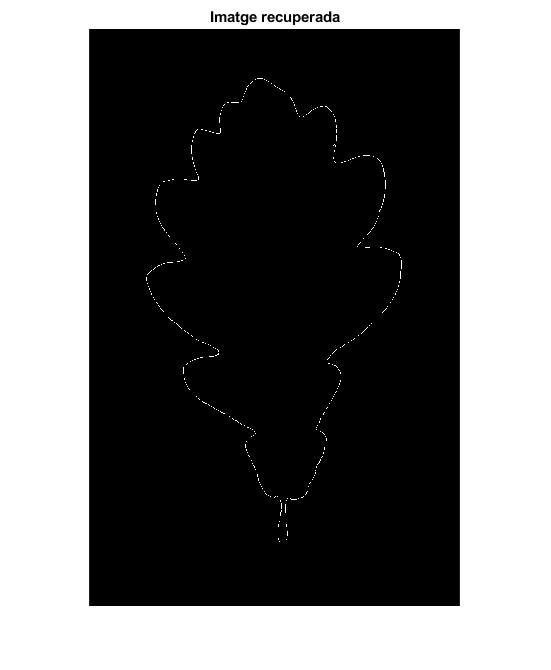


%Recuperem la imatge original per comprovar que el procès és reversible
ss = ifft(z); %Transformada de Fourier inversa
files = round(real(ss) + mig(1));
cols = round(imag(ss) + mig(2));
aux(:,:)=0;
aux(sub2ind(size(aux),files,cols))=1;
figure,imshow(aux), title('Imatge recuperada')